f = @(t) cos((pi * t.^2) / 2)';
a = 0;
b = pi;
n1 = 10.^3;
n2 = 10.^5;

I3 = composite_simpsons1(f, a, b, n1)

I3 =    0.523698543881365


I4 = composite_simpsons1(f, a, b, n2)

I4 =    0.523698543726226



ExactSol = fresnelc(pi)

ExactSol =    0.523698543726229


% ExactSol = 0.523698543726229


Err1 = abs(I3 - ExactSol)

Err1 =      1.551367923013913e-10


Err2 = abs(I4 - ExactSol)

Err2 =      2.109423746787797e-15


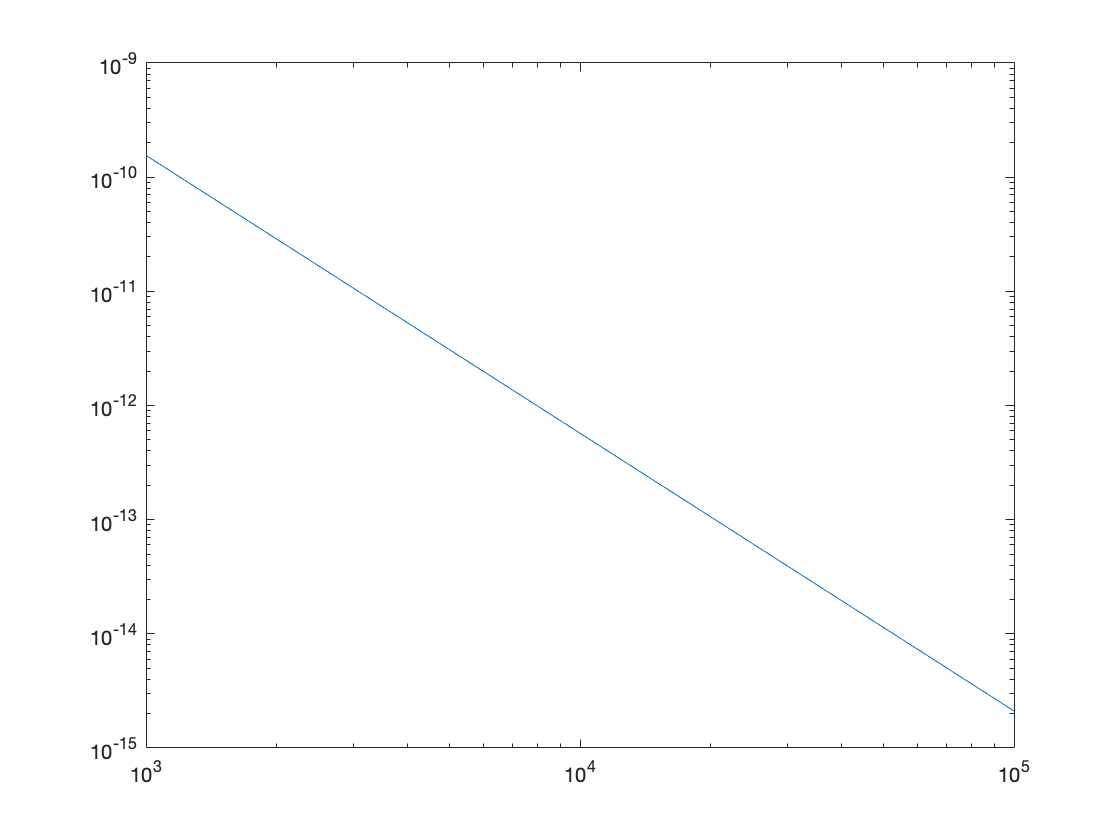


% Err1 = 1.551367923013913e-10
% Err2 = 2.109423746787797e-15

loglog([n1,n2], [Err1, Err2])

function I = composite_simpsons1(f, a, b, n)
h = (b - a) / n;

sI0 = f(a) + f(b);
sI1 = 0;
sI2 = 0;

for i = 1:n - 1
    x = a + i * h;
    if mod(i, 2) == 0
        sI2 = sI2 + f(x);
    else
        sI1 = sI1 + f(x);
    end
end

I = (h / 3) * (sI0 + 2 * sI2 + 4 * sI1);
end